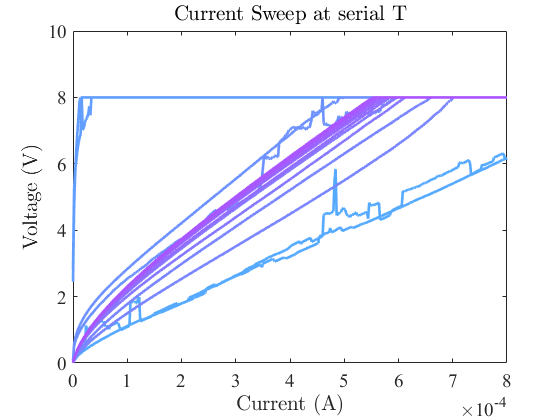

clear;clc;clf("reset");
%Path = 'M:\309test\20230807\409-2-15_0.2Hz_retest\Isweep'; % Folder path of series test data
defaultPath = 'I:\WorkSpace\ResearchGroup\RecentWork\YBCO\Bolometer\Data\309test\20230807\';
Path = uigetdir(defaultPath);
File = dir(fullfile(Path,'*.mat')); % Extract all .mat files in the folder
FileNames = {File.name}';
len = length(FileNames);
loop = 1;
while ~contains(FileNames{loop},'Isweep')
    loop = loop+1;
end
load([Path, '\', FileNames{loop}]);  % Determine the matrix size according to the first file
wid = length(curr);
VoltList = zeros(len,wid);  % Initialize the voltage data matrix
CurrList = zeros(len,wid);  % Initialize the current data matrix
TempList = zeros(len,1)*nan;  % Initialize the temperature data matrix
pat = regexpPattern('\d+.\d+K');  % Define the temperature regular matching pattern
for i=1:len
    if contains(FileNames{i},'Isweep')
        load([Path, '\', FileNames{i}]);
        VoltList(i,:) = volt;
        CurrList(i,:) = curr;
        Reresult = extract(FileNames{i},pat);
        TempList(i) = str2double(Reresult{1}(1:end-1));
    end
end
Numplot = 20;
colororder(cool(size(CurrList(1:floor(len/Numplot):len,:),1)));
plot(CurrList(1:floor(len/Numplot):len,:)',VoltList(1:floor(len/Numplot):len,:)',"LineWidth",2)
title('Current Sweep at serial T',"Interpreter","latex");
xlabel('Current (A)',"Interpreter","latex");
ylabel('Voltage (V)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');

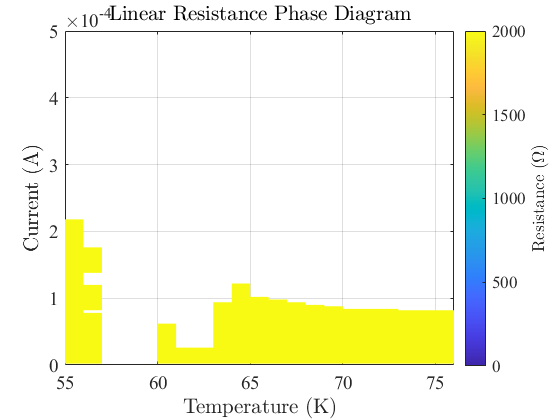

% Identify and process all voltage compliance data points
VoltCompInd = find(VoltList >= 2-1e-3);
VoltList(VoltCompInd) = 0;
CurrList(VoltCompInd) = Inf;

% Calculate the linear resistance and plot phase diagram
Start = 0;  % 0 for forward sweep and wid/2 for backward
Resis_contract = 0.0;
Curr = CurrList(:,Start+1:Start+wid/2)';
Volt_corr = VoltList(:,Start+1:Start+wid/2)'-CurrList(:,Start+1:Start+wid/2)'*Resis_contract;
[X,Y] = meshgrid(TempList',curr(Start+1:Start+wid/2));
Resis_linear = Volt_corr./Curr;

surf(X,Y,Resis_linear,"FaceColor","flat");
colormap parula; shading flat;box on;
view([0 90.00]);caxis([0 2e3]);
xlim([min(TempList) max(TempList)]);
title('Linear Resistance Phase Diagram',"Interpreter","latex")
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Current (A)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');
% set(gca,'YScale','log') % This line for LogScale Current Sweep
c = colorbar; c.Label.String = 'Resistance ($\Omega$)';
c.Label.Interpreter = 'latex';

% Plot the Linear Resistance vs. Temperature
Resis_linear_ext = Resis_linear(2:floor(wid/30):wid/2,:);
colororder(parula(size(Resis_linear_ext,1)));

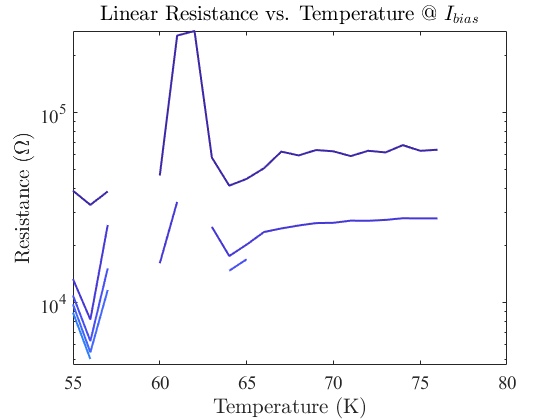

semilogy(TempList,Resis_linear_ext,"LineWidth",1.5);
title('Linear Resistance vs. Temperature @ $I_{bias}$',"Interpreter","latex");
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Resistance ($\Omega$)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');

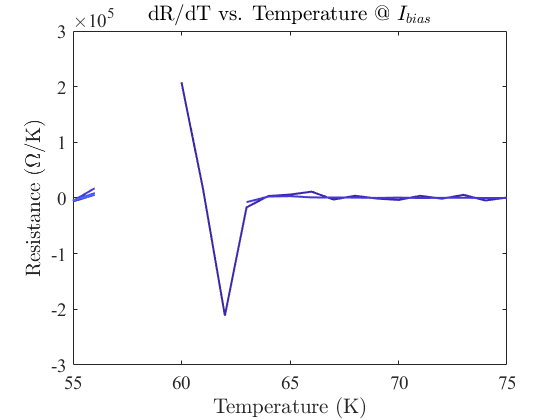


% Plot the dR/dT vs. Temperature
dR = diff(Resis_linear_ext,1,2);
dR(isnan(dR)) = 0;
dRdT = dR*diag(1./diff(TempList));
dRdT(find(dRdT == 0)) = NaN;
plot(TempList(1:end-1),dRdT',"LineWidth",1.5)
title('dR/dT vs. Temperature @ $I_{bias}$',"Interpreter","latex");
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Resistance ($\Omega$/K)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');

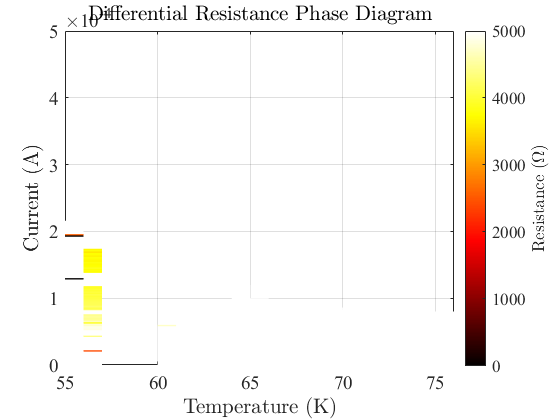


% Plot the dV/dI (differential resistance) phase diagram
Resis_diff = diff(Volt_corr,1,1)./diff(Curr,1,1);
surf(X(1:end-1,:),(Y(1:end-1,:)),Resis_diff,"FaceColor","flat");
colormap hot; shading flat;box on;
view([0 90.00]);caxis([0, 5000]);
xlim([min(TempList) max(TempList)])
title('Differential Resistance Phase Diagram',"Interpreter","latex")
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Current (A)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');
% set(gca,'YScale','log');ylim([1e-7 3e-3]) % This line for LogScale Current Sweep
c = colorbar; c.Label.String = 'Resistance ($\Omega$)';
c.Label.Interpreter = 'latex';

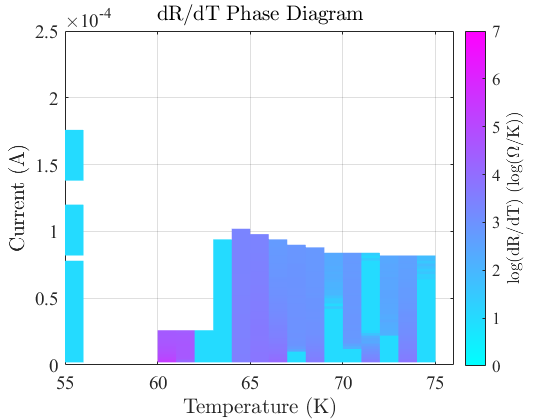


% Plot the dV/dI (differential resistance) phase diagram
Resis_diffT = diff(Resis_linear,1,2);
Resis_diffT(find(Resis_diffT<=0)) = 10;
surf(X(:,1:end-1),(Y(:,1:end-1)),abs(log10(Resis_diffT)),"FaceColor","flat");
colormap cool; shading flat;box on;
view([0 90.00]);caxis([0, 7]);
xlim([min(TempList) max(TempList)]);
title('dR/dT Phase Diagram',"Interpreter","latex")
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Current (A)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');
% set(gca,'YScale','log');ylim([1e-7 3e-3]); % This line for LogScale Current Sweep
c = colorbar; c.Label.String = 'log(dR/dT) (log($\Omega$/K))';
c.Label.Interpreter = 'latex';